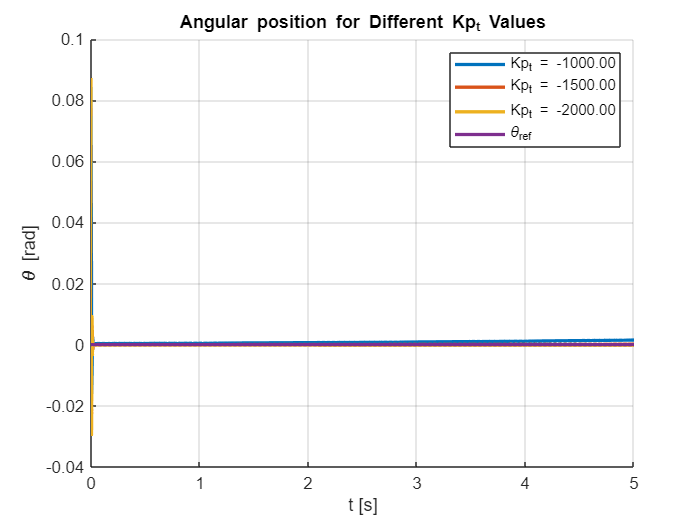

run("wheel/wheel_parameters.m")


% Initial state
X0 = [0; 0; 5*pi/180; 0];

% Inner Loop Regulator (fixed)
Kp_v = 0;
Td_v = 0;
Ti_v = 0;

% Outer Loop Regulator (test different Kp values)
Kp_t_values = -[1000 1500 2000];   % values to compare
Td_t = 1;
Ti_t = 0;

% Simulation time
t = 0:0.01:5;
Tsim = 5;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];

figure;
hold on;
grid on;

for i = 1:length(Kp_t_values)

    % Update current Kp
    Kp_t = Kp_t_values(i);

    % Run simulation
    out = sim("wheel/wheel_robot_sim.slx");

    % Extract position
    theta_v = out.simout.signals.values(:,3);
    t_v = out.tout;

    % Plot
    plot(t_v, theta_v, 'LineWidth', 2, ...
        'DisplayName', sprintf('Kp_t = %.2f', Kp_t));
end

% Extract theta_ref
theta_ref = out.simout1.signals.values;
plot(t_v, theta_ref, 'LineWidth', 2,"DisplayName","\theta_{ref}");

xlabel('t [s]');
ylabel('\theta [rad]');
title('Angular position for Different Kp_t Values');
legend('show');

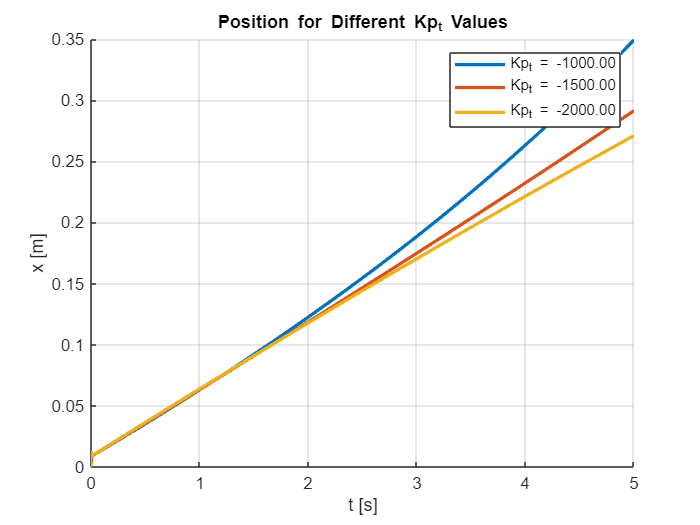


figure;
hold on;
grid on;

for i = 1:length(Kp_t_values)

    % Update current Kp
    Kp_t = Kp_t_values(i);

    % Run simulation
    out = sim("wheel/wheel_robot_sim.slx");

    % Extract position
    x_v = out.simout.signals.values(:,1);
    t_v = out.tout;

    % Plot
    plot(t_v, x_v, 'LineWidth', 2, ...
        'DisplayName', sprintf('Kp_t = %.2f', Kp_t));
end

xlabel('t [s]');
ylabel('x [m]');
title('Position for Different Kp_t Values');
legend('show');